# 卫星地距几何

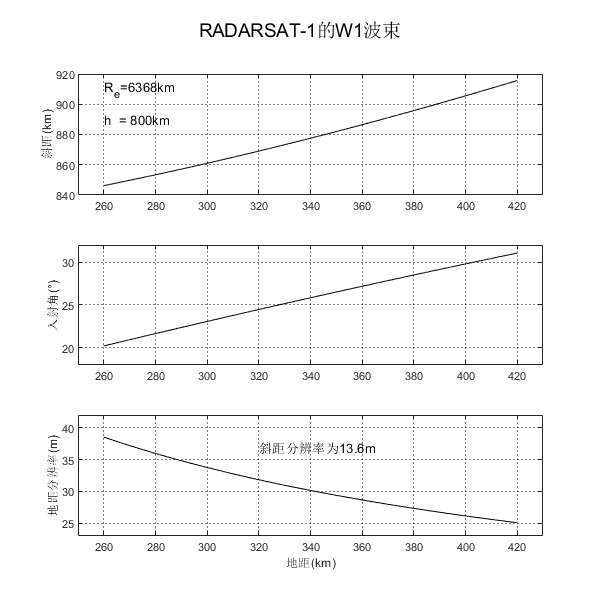

% 参数设置
Re = 6.368e+6;           % 地球半径
h = 8e+5;                % 轨道高度
delta_R = 13.6;          % 斜距分辨率
% 参数计算
Rs = Re + h;             % 轨道半径
% 变量设置
G = linspace(2.6e+5,4.2e+5,3000);       % 地距设置
% 变量计算
R0 = sqrt(Rs^2+Re^2-2*Re*Rs*cos(G/Re)); % 斜距设置
theta_i = asin(Rs./R0.*sin(G/Re));      % 入射角设置
delta_G = delta_R./theta_i;             % 地距分辨率设置
% 绘图
H1 = figure;
set(H1,'position',[200,200,600,600]);
subplot(311),plot(G*1e-3,(R0)*1e-3,'k'),grid on
set(gca,'GridLineStyle',':','GridColor','k','GridAlpha',1); % 设置网格虚线
axis([250 430,840 920]),ylabel('斜距(km)')
text(260,910,'R_e=6368km','Color','black','HorizontalAlignment','left')
text(260,890,'h  = 800km','Color','black','HorizontalAlignment','left')
subplot(312),plot(G*1e-3,theta_i/pi*180,'k'),grid on
set(gca,'GridLineStyle',':','GridColor','k','GridAlpha',1); % 设置网格虚线
axis([250 430, 18  32]),ylabel('入射角(°)')
subplot(313),plot(G*1e-3,delta_G,'k'),grid on
set(gca,'GridLineStyle',':','GridColor','k','GridAlpha',1); % 设置网格虚线
axis([250 430, 23  42]),xlabel('地距(km)'),ylabel('地距分辨率(m)')
text(320, 37,'斜距分辨率为13.6m','Color','black','HorizontalAlignment','left')
suptitle('RADARSAT-1的W1波束')